## Motion Place

clear
close all
syms t
Clover=sin(2*t)+1/4*sin(6*t);
Scale=1.33;
theta=0;
[x,y]=servoPoints(Clover,Scale,theta);
% figure(1)
%  for i=1:length(x)
%      plot(x(1:i),y(1:i),'--r')
%      hold on
%      pause(1/10)
%  end

## DH parameteres

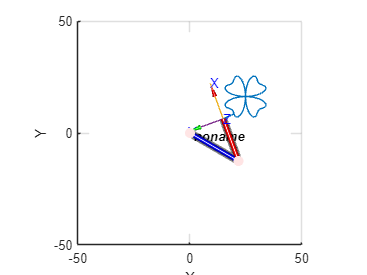

close all
l1=25;
l2=20;
offset=deg2rad([-30,140]);
DH=[0,0,l1,0,0,offset(1);
    0,0,l2,0,0,offset(2)];
L(1)=Link(DH(1,:));
L(2)=Link(DH(2,:));
robotServo = SerialLink(L);
position=eye(4);
for i=1:length(DH(:,1))
    position=position*(trotz(DH(i,1)+DH(i,6))*transl(0,0,DH(i,2))*transl(DH(i,3),0,0)*trotx(DH(i,4)));
end
position;
fromBase=[x+position(1,4);y+position(2,4)];
figure(2)
%robotServo.plot([0,0])
hold on
plot(fromBase(1,:),fromBase(2,:))
robotServo.plot([0,0])

## Inverse Kinematics

% fromBase=position*fromBase;
% fromBase;
q_1=double.empty(length(x),0);
prev=[0,0];
for i=1:length(x)
    vals=[fromBase(1,i),fromBase(2,i)];
    q=robotServo.ikine(transl(vals(1),vals(2),0),prev,[1,1,0,0,0,0]);
    q_1(i,1)=q(1);
    q_1(i,2)=q(2);
    prev=[q(1),q(2)];
end

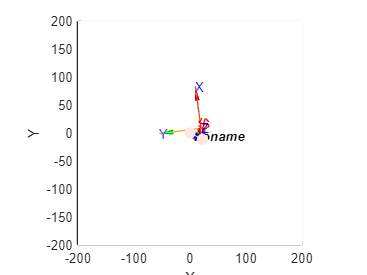

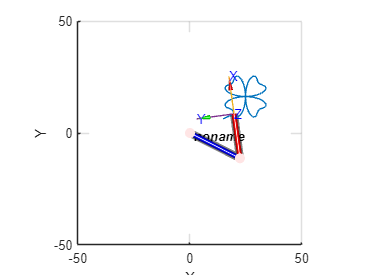

% for i=1:length(q_1)
%     robotServo.plot(q_1(i,:))
% end
robotServo.plotopt={'tilesize',200};
figure(11)
hold on
for i=1:length(q_1)
    robotServo.plot(q_1(i,:));
    plot(fromBase(1,:),fromBase(2,:),'--r')
    pause(1/100)
end

function p_x=getPoints(Clover,Scale,theta,amount)
    syms t
    R = [cosd(theta) -sind(theta); sind(theta) cosd(theta)];
    th=linspace(0,2*pi,amount);
    r=double(subs(Clover*Scale,t,th));
    [x,y]=pol2cart(th,r);
    p_x=(R*[x;y]);
    p_x=p_x+15*Scale/2;
end
function [x,y]=servoPoints(Clover,Scale,theta)
    syms t
    Max=max(subs(Clover,t,solve(diff(Clover,t)==0)));
    Clover=15/2*Clover/Max;
    p=getPoints(Clover,Scale,theta,100);
    x=p(1,:);
    y=p(2,:);
    w=zeros(length(x),2);
    for i=1:length(x)
        w(i,1)=x(i);
        w(i,2)=y(i);
    end
    [k,~] = dsearchn(w,[0,0]);
    x=[0,x(k:end), x(1:k-1),x(k)];
    y=[0,y(k:end), y(1:k-1),y(k)];
end
